clc
clear
warning off
%load GEFCOMdata(6 columns- YYYYMMDD,HH,Zonal price,System load,Zonal load, day of the week)
data = readtable("GEFCOMdata.csv");
data = table2array(data);

TASK1 - Figure of GEFCom2014 hourly locational marginal prices and system load in 1.1.2011 - 17.12.2013.(P2)

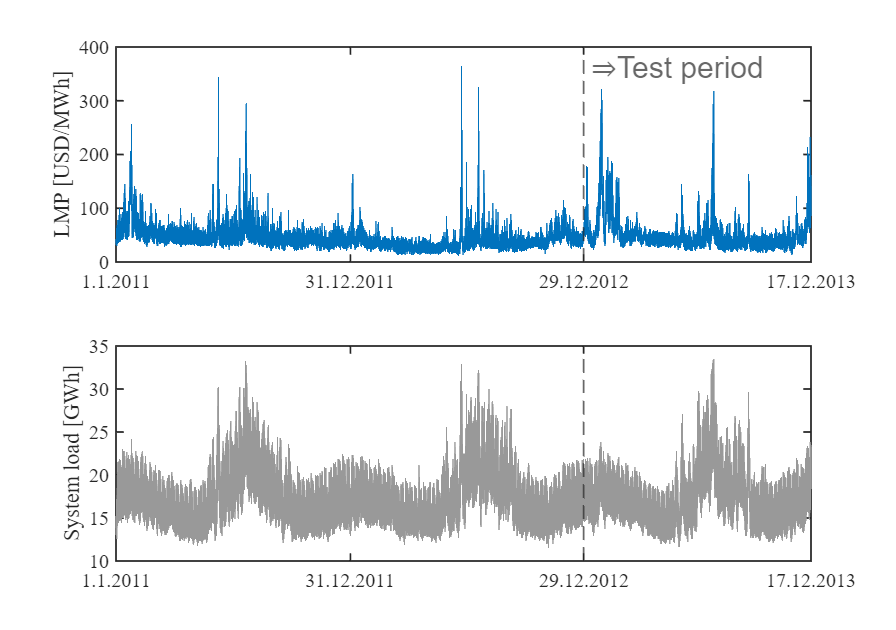

%{
GEFCom2014 hourly locational marginal prices (LMPs; top) and
hourly day-ahead predictions of system load (bottom) for the period 1.1.2011–
17.12.2013.The vertical dashed lines mark the beginning of the test period.
%}
figure('units','normalized','position',[0.01,0.01,0.8,1])
subplot(2,1,1)
plot(data(:,3))
xline(728*24+1,'--','⇒Test period','Linewidth',1,'LabelOrientation','horizontal','FontSize',18)
xticks([0 365*24 728*24+1 size(data,1)])
xticklabels({'1.1.2011','31.12.2011','29.12.2012','17.12.2013'});
xlim([0 size(data,1)]);
yticks([0:100:400])
ylabel('LMP [USD/MWh]');
set(gca,'linewidth',1,'fontsize',12,'fontname','Times');
subplot(2,1,2)
plot(data(:,4)/1000,'color',[0.6, 0.6, 0.6])
xline(728*24+1,'--','Linewidth',1)
xticks([0 365*24 728*24+1 size(data,1)]);
xticklabels({'1.1.2011','31.12.2011','29.12.2012','17.12.2013'});
xlim([0 size(data,1)]);
ylabel('System load [GWh]');
set(gca,'linewidth',1,'fontsize',12,'fontname','Times');

%Bulid arx model and call the function
tic
endd = 728;%the last day of calibration window
ndays = size(data,1)/24-endd;%predicted days 354(from 729 to 1082)
arx_result = nan(ndays*24,728-28+1);%forecast result matrix starts from win 28 to win 728
for gap = 28:728 %window sets
    startd = endd-gap+1 ;%start days of different windows
    arx_result(:,gap-27) = epf_arx(data,ndays,startd,endd);%call the builded arx model function 
end
toc

历时 434.555645 秒。


TASK2.1 - TABLE I (P2)- ARX's mae and %CHNG

%%MAE FOR SELECTED CALIBRATION WINDOW SETS IN THE ARX MODELS
abs_err = nan(ndays*24,14);
price_real = data(728*24+1:end,3);%price from d_729-d_end
%Win(28)
abs_err(:,1) = abs(price_real-arx_result(:,1));
%Win(364)
abs_err(:,2) = abs(price_real-arx_result(:,364-28+1));
%AW(364,728)
abs_err(:,3)= abs(price_real-mean([arx_result(:,364-28+1) arx_result(:,728-28+1)],2));
%Win(728)
abs_err(:,4) = abs(price_real-arx_result(:,728-28+1));
%AW(28:728)
abs_err(:,5) = abs(price_real-mean(arx_result,2));
%AW(28:7:728)
abs_err(:,6) = abs(price_real-mean(arx_result(:,1:7:end),2));
%AW(28:14:728)
abs_err(:,7) = abs(price_real-mean(arx_result(:,1:14:end),2));
%AW(28:28:728)
abs_err(:,8) = abs(price_real-mean(arx_result(:,1:28:end),2));
%AW(56,728)
abs_err(:,9) = abs(price_real-mean([arx_result(:,56-28+1) arx_result(:,728-28+1)],2));
%AW(28,728)
abs_err(:,10) = abs(price_real-mean([arx_result(:,1) arx_result(:,728-28+1)],2));
%AW(28:28:84,714:7:728)
abs_err(:,11) = abs(price_real-mean([arx_result(:,1:28:84-28+1) arx_result(:,714-28+1:7:728-28+1)],2)) ;
%AW(28,56,728)
abs_err(:,12) = abs(price_real-mean([arx_result(:,1) arx_result(:,56-28+1) arx_result(:,728-28+1)],2));
%AW(28,56,364,728)
abs_err(:,13) = abs(price_real-mean([arx_result(:,1) arx_result(:,56-28+1) arx_result(:,364-28+1) arx_result(:,728-28+1)],2));
%AW(28,56,721,728)
abs_err(:,14) = abs(price_real-mean([arx_result(:,1) arx_result(:,56-28+1) arx_result(:,721-28+1) arx_result(:,728-28+1)],2));
mae_arx = mean(abs_err,1)';
mae_arx_dis = round(mae_arx,3);
%%RELATIVE CHANGES (%CHNG.) WITH RESPECT TO THE WIN(728) MAE IN THE ARX MODELS
per_chng_arx = nan(14,1);
per_chng_arx(1) = round(log(mae_arx(4)/mae_arx(1))*100,1);%Win(28)'s relative changes
for i = 2:14
    per_chng_arx(i) = round(log(mae_arx(4)/mae_arx(i))*100,2);
end

TASK2.2 - - TABLE I (P2)- NARX's mae and %CHNG

%%MAE FOR SELECTED CALIBRATION WINDOW SETS IN THE NARX MODELS
ndays = 354;
narx_result = readtable("narxoutput.csv");
narx_result = table2array(narx_result);
narx_abs_err = nan(ndays*24,14);
price_real = data(728*24+1:end,3);%price from d_729-d_end
%Win(28)
narx_abs_err(:,1) = abs(price_real-narx_result(:,1));
%Win(364)
narx_abs_err(:,2) = abs(price_real-narx_result(:,364-28+1));
%AW(364,728)
narx_abs_err(:,3)= abs(price_real-mean([narx_result(:,364-28+1) narx_result(:,728-28+1)],2));
%Win(728)
narx_abs_err(:,4) = abs(price_real-narx_result(:,728-28+1));
%AW(28:728)
narx_abs_err(:,5) = abs(price_real-mean(narx_result,2));
%AW(28:7:728)
narx_abs_err(:,6) = abs(price_real-mean(narx_result(:,1:7:end),2));
%AW(28:14:728)
narx_abs_err(:,7) = abs(price_real-mean(narx_result(:,1:14:end),2));
%AW(28:28:728)
narx_abs_err(:,8) = abs(price_real-mean(narx_result(:,1:28:end),2));
%AW(56,728)
narx_abs_err(:,9) = abs(price_real-mean([narx_result(:,56-28+1) narx_result(:,728-28+1)],2));
%AW(28,728)
narx_abs_err(:,10) = abs(price_real-mean([narx_result(:,1) narx_result(:,728-28+1)],2));
%AW(28:28:84,714:7:728)
narx_abs_err(:,11) = abs(price_real-mean([narx_result(:,1:28:84-28+1) narx_result(:,714-28+1:7:728-28+1)],2)) ;
%AW(28,56,728)
narx_abs_err(:,12) = abs(price_real-mean([narx_result(:,1) narx_result(:,56-28+1) narx_result(:,728-28+1)],2));
%AW(28,56,364,728)
narx_abs_err(:,13) = abs(price_real-mean([narx_result(:,1) narx_result(:,56-28+1) narx_result(:,364-28+1) narx_result(:,728-28+1)],2));
%AW(28,56,721,728)
narx_abs_err(:,14) = abs(price_real-mean([narx_result(:,1) narx_result(:,56-28+1) narx_result(:,721-28+1) narx_result(:,728-28+1)],2));
mae_narx = mean(narx_abs_err,1)';
mae_narx_dis = round(mae_narx,3);
per_chng_narx = nan(14,1);
per_chng_narx(1) = round(log(mae_narx(4)/mae_narx(1))*100,1);%Win(28)'s relative changes
for i = 2:14
    per_chng_narx(i) = round(log(mae_narx(4)/mae_narx(i))*100,2);
end
%display the MAE and %CHNG.
stats = [mae_arx_dis,per_chng_arx,mae_narx_dis,per_chng_narx];
names = {'ARX_MAE','ARX_%chng.',' NARX_MAE','NARX_%chng.'};
rowname = {'Win(28)','Win(364)','AW(364,728)','Win(728)','AW(28:728)','AW(28:7:728)',...
    'AW(28:14:728)','AW(28:28:728)','AW(56,728)','AW(28,728)','AW(28:28:84,714:7:728)',...
    'AW(28,56,728)','AW(28,56,364,728)','AW(28,56,721,728)'};
T = array2table(stats, 'VariableNames',names,'RowNames',rowname);
disp(T)

                              ARX_MAE    ARX_%chng.     NARX_MAE    NARX_%chng.
                              _______    __________    _________    ___________

    Win(28)                    7.758       -10.5        10.028         -23.6   
    Win(364)                   7.147       -2.35         8.575         -7.93   
    AW(364,728)                7.032       -0.72         7.811          1.41   
    Win(728)                   6.982           0         7.922             0   
    AW(28:728)                 6.898         1.2         7.071         11.37   
    AW(28:7:728)               6.891         1.3         7.058         11.54   
    AW(28:14:728)              6.879        1.48         7.097         10.99   
    AW(28:28:728)              6.858        1.78         7.117         10.72   
    AW(56,728)                 6.637        5.05         7.441          6.26   
    AW(28,728)                 6.591        5.76         8.025          -1.3   
    AW(28:28:84,714:7:728)     6.514   

TASK3 - Fig.2 

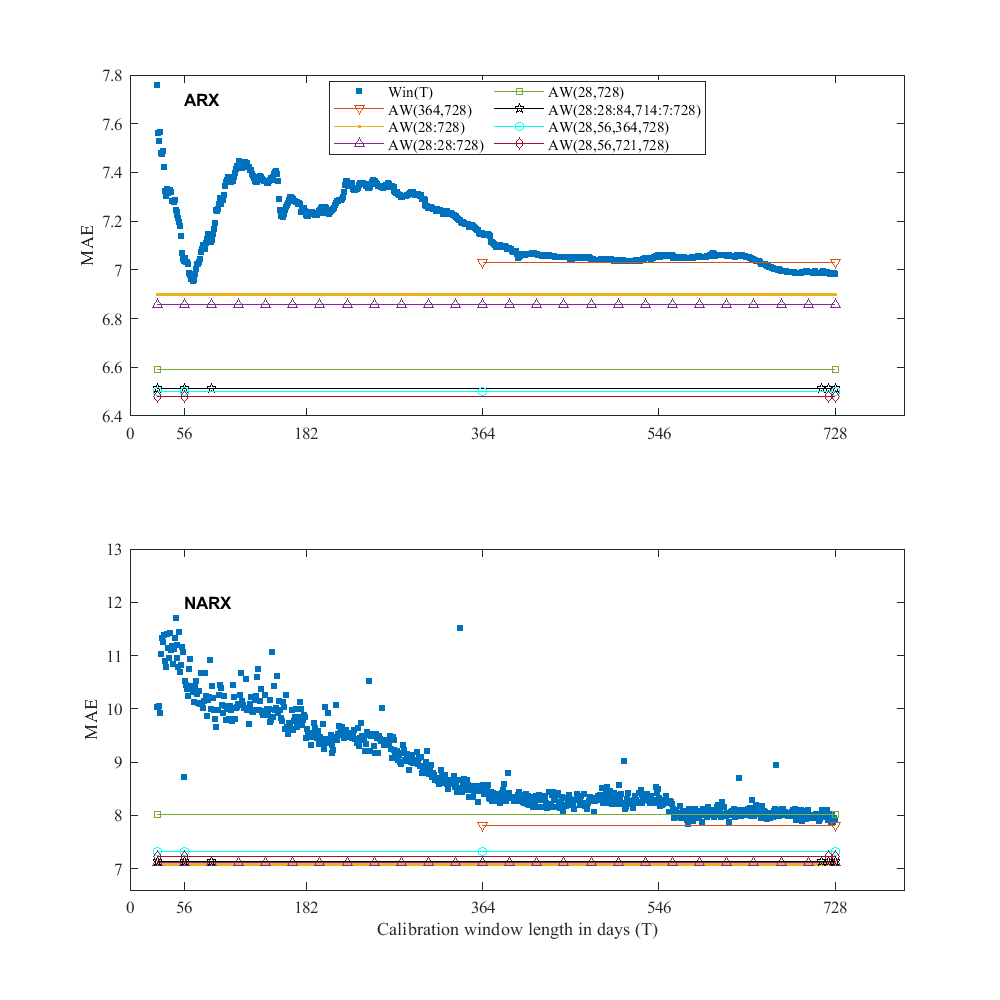

%{
Fig. 2. Mean Absolute Errors (MAE; in percent) as a function of the window 
length T = 28, ..., 728 (blue circles) and obtained by averaging forecasts 
across calibration windows (lines with symbols representing window lengths) 
for the ARX (top) and NARX (bottom) models. 
%}
mae_win = nan(728,1);
mae_narx_win = nan(728,1);%
for i = 1:701
    mae_win(i+27,1) = round(mean(abs(price_real - arx_result(:,i))),3);
    mae_narx_win(i+27,1) = round(mean(abs(price_real - narx_result(:,i))),3);%

end 
AW_mae = mae_arx([3 5 8 10:11 13:14],1);
NARX_AW_mae = mae_narx([3 5 8 10:11 13:14],1);

figure('units','normalized','position',[0.1,0.1,0.6,1])
subplot(2,1,1)
%Win(28)-win(728)
plot(mae_win,'.','MarkerSize',10)
%yticks([6.4:0.2:7.8])
hold on 
%AW(364,728)
x1 =(364:728)';
y1=(ones(size(x1))*AW_mae(1));
plot(x1,y1,'-v','MarkerSize',5,'MarkerIndices',[1 length(y1)]);
%AW(28:728)
x2 = (28:728)';
y2=(ones(size(x2))*AW_mae(2));
plot(x2,y2,'.-','MarkerIndices',1:length(y2));
%AW(28:28:728)
x3 = (28:728)';
y3=(ones(size(x3))*AW_mae(3));
plot(x3,y3,'-^','MarkerSize',5,'MarkerIndices',1:28:length(y3));
%AW(28:28:84,714:7:728)
x4 = (28:728)';
y4=(ones(size(x4))*AW_mae(4));
plot(x4,y4,'-s','MarkerSize',5,'MarkerIndices',[1 length(y4)]);
%AW(364,728)
x5 = (28:728)';
y5=(ones(size(x5))*AW_mae(5));
plot(x5,y5,'-pk','MarkerIndices',[1:28:84-28+1 714-28+1:7:728-28+1]);
%AW(28,56,364,728)
x6 = (28:728)';
y6=(ones(size(x6))*AW_mae(6));
plot(x6,y6,'-oc','MarkerSize',5,'MarkerIndices',[1 56-28+1 364-28+1 length(y6)]);
%AW(28,56,721,728)
x7 = (28:728)';
y7=(ones(size(x7))*AW_mae(7));
plot(x7,y7,	'-dm','MarkerSize',5,'MarkerIndices',[1 56-28+1 721-28+1 length(y7)],'color',[0.6350 0.0780 0.1840]);
xticks([0 56 182 364 546 728])
xticklabels({'0','56','182','364','546','728'});
yticks([6.4:0.2:7.8])
ylabel('MAE','FontSize',10);
text(56,7.7,'ARX','FontWeight','bold')
legend('Win(T)','AW(364,728)','AW(28:728)','AW(28:28:728)','AW(28,728)','AW(28:28:84,714:7:728)'...
    ,'AW(28,56,364,728)','AW(28,56,721,728)','NumColumns',2,'location', 'best')
set(gca,'linewidth',1,'fontsize',10,'fontname','Times');
%subplot(2,1,2)
subplot(2,1,2)
%Win(28)-win(728)
plot(mae_narx_win,'.','MarkerSize',10)
%yticks([6.4:0.2:7.8])
hold on 
%AW(364,728)
x1 =(364:728)';
y1=(ones(size(x1))*NARX_AW_mae(1));
plot(x1,y1,'-v','MarkerSize',5,'MarkerIndices',[1 length(y1)]);
%AW(28:728)
x2 = (28:728)';
y2=(ones(size(x2))*NARX_AW_mae(2));
plot(x2,y2,'.-','MarkerIndices',1:length(y2));
%AW(28:28:728)
x3 = (28:728)';
y3=(ones(size(x3))*NARX_AW_mae(3));
plot(x3,y3,'-^','MarkerSize',5,'MarkerIndices',1:28:length(y3));
%AW(28:28:84,714:7:728)
x4 = (28:728)';
y4=(ones(size(x4))*NARX_AW_mae(4));
plot(x4,y4,'-s','MarkerSize',5,'MarkerIndices',[1 length(y4)]);
%AW(364,728)
x5 = (28:728)';
y5=(ones(size(x5))*NARX_AW_mae(5));
plot(x5,y5,'-pk','MarkerIndices',[1:28:84-28+1 714-28+1:7:728-28+1]);
%AW(28,56,364,728)
x6 = (28:728)';
y6=(ones(size(x6))*NARX_AW_mae(6));
plot(x6,y6,'-oc','MarkerSize',5,'MarkerIndices',[1 56-28+1 364-28+1 length(y6)]);
%AW(28,56,721,728)
x7 = (28:728)';
y7=(ones(size(x7))*NARX_AW_mae(7));
plot(x7,y7,	'-dm','MarkerSize',5,'MarkerIndices',[1 56-28+1 721-28+1 length(y7)],'color',[0.6350 0.0780 0.1840]);
xticks([0 56 182 364 546 728])
xticklabels({'0','56','182','364','546','728'});
ylim([6.6 13])
ylabel('MAE','FontSize',10);
text(56,12,'NARX','FontWeight','bold')
xlabel('Calibration window length in days (T)','FontSize',10);
set(gca,'linewidth',1,'fontsize',10,'fontname','Times');

TASK4 -Fig.3

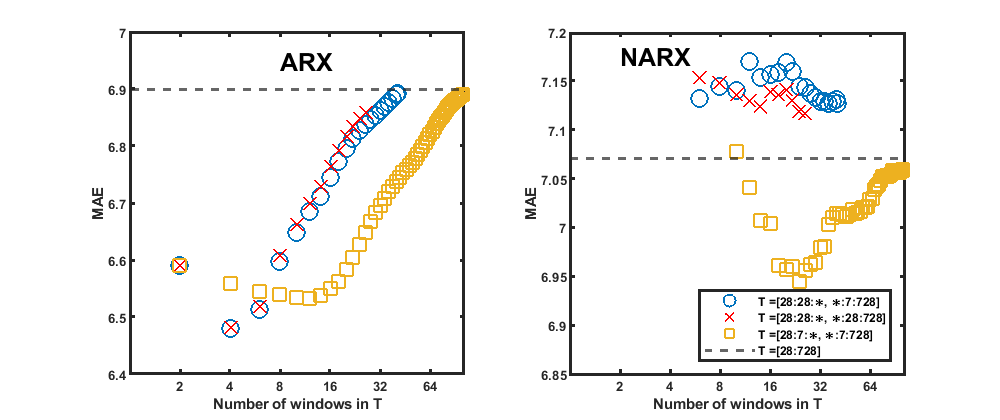

%{
Fig. 3. Mean Absolute Errors (MAE; in percent) for the ARX (left) and
NARX (right) models as a function of the number of windows in T , for an
iterative procedure described in the text. We use a wildcard (∗) to denote the
‘middle’ windows in T = {28:m:∗, ∗:n:728} and let m, n = 7 or 28.
%}
%T1 = T ={28:28:∗, ∗:7:728}
num1 = ceil((728-28+1)/7/2);
mae_arx_T1 = nan(num1,1);
mae_narx_T1 = nan(num1,1);%
win_arx_T1 = nan(num1,1);
win_narx_T1 = nan(num1,1);%
for i=1:num1
    ind1 = 28:28:28*i;
    ind2 = 728-7*(i-1):7:728;
    ind = [ind1 ind2]-28+1;
    win_arx_T1(i) = size(ind,2);
    win_narx_T1(i) = size(ind,2);
    mae_arx_T1(i) = mean(abs(price_real-mean(arx_result(:,ind),2))); 
    mae_narx_T1(i) = mean(abs(price_real-mean(narx_result(:,ind),2)));
    if ind1(end) == ind2(1)
        j = ind1(end);
        ind1(end) = [];
        ind2(1) = [];
        win_arx_T1(i+1:end)=[];
        win_narx_T1(i+1:end)=[];
        mae_arx_T1(i+1:end)=[];
        mae_narx_T1(i+1:end)=[];
        ind = [ind1 j ind2]-28+1;
        win_arx_T1(i) = size(ind,2);
        win_narx_T1(i) = size(ind,2);
        mae_arx_T1(i) = mean(abs(price_real-mean(arx_result(:,ind),2)));
        mae_narx_T1(i) = mean(abs(price_real-mean(narx_result(:,ind),2)));
        break
    end    
end
%T2 ={28:28:∗, ∗:28:728}
num2 = ceil((728-28+1)/28/2);
mae_arx_T2 = nan(num2,1);
mae_narx_T2 = nan(num2,1);
win_arx_T2 = nan(num2,1);
win_narx_T2 = nan(num2,1);
for i =1:num2
    ind1 = 28:28:28*i;
    ind2 = 728-28*(i-1):28:728;
    ind = [ind1 ind2]-28+1;
    win_arx_T2(i) = size(ind,2);
    win_narx_T2(i) = size(ind,2);
    mae_arx_T2(i) = mean(abs(price_real-mean(arx_result(:,ind),2)));
    mae_narx_T2(i) = mean(abs(price_real-mean(narx_result(:,ind),2)));
end
%T3 ={28:7:∗, ∗:7:728}
num3 = ceil((728-28+1)/7/2);
mae_arx_T3 = nan(num3,1);
mae_narx_T3 = nan(num3,1);
win_arx_T3 = nan(num3,1);
win_narx_T3 = nan(num3,1);
for i=1:num3
    ind1 = 28:7:28+7*(i-1);
    ind2 = 728-7*(i-1):7:728;
    ind = [ind1 ind2]-28+1;
    if ind1(end) == ind2(1)
        j = ind1(end);
        ind1(end) = [];
        ind2(1) = [];
        ind = [ind1 j ind2]-28+1;
    end    
    win_arx_T3(i) = size(ind,2);
    win_narx_T3(i) = size(ind,2);
    mae_arx_T3(i) = mean(abs(price_real-mean(arx_result(:,ind),2))); 
    mae_narx_T3(i) = mean(abs(price_real-mean(narx_result(:,ind),2)));
end
%T4 ={28:728}
mae_arx_T4 = AW_mae(2);
mae_narx_T4 = NARX_AW_mae(2);
figure('units','normalized','position',[0.1,0.1,1.5,1])
%arx
subplot(1,2,1)
plot(log2(win_arx_T1),mae_arx_T1,'o','Color',[0 0.4470 0.7410],'MarkerSize',10,'LineWidth',1)
hold on 
plot(log2(win_arx_T2),mae_arx_T2,'rx','MarkerSize',10,'LineWidth',1)
hold on 
plot(log2(win_arx_T3),mae_arx_T3,'s','Color',[0.9290 0.6940 0.1250],'MarkerSize',10,'LineWidth',1)
hold on
yline(mae_arx_T4,'--','Linewidth',1.5) 
text(3,6.95,'ARX','FontSize',15,'fontweight','bold')
xlim([0 round(log2(101),1)])
xticks([1 2 3 4 5 6]);
xticklabels({'2','4','8','16','32','64'});
xlabel('Number of windows in T');
ylim([6.4 7])
ylabel('MAE');
set(gca,'linewidth',1.5,'fontsize',8,'fontweight','bold');
%narx
subplot(1,2,2)
plot(log2(win_narx_T1),mae_narx_T1,'o','Color',[0 0.4470 0.7410],'MarkerSize',10,'LineWidth',1)
hold on 
plot(log2(win_narx_T2),mae_narx_T2,'rx','MarkerSize',10,'LineWidth',1)
hold on 
plot(log2(win_narx_T3),mae_narx_T3,'s','Color',[0.9290 0.6940 0.1250],'MarkerSize',10,'LineWidth',1)
hold on
yline(mae_narx_T4,'--','Linewidth',1.5) 
text(1,7.175,'NARX','FontSize',15,'fontweight','bold')
xlim([0 round(log2(101),1)])
xticks([1 2 3 4 5 6]);
xticklabels({'2','4','8','16','32','64'});
xlabel('Number of windows in T');
ylim([6.85 7.2])
ylabel('MAE');
set(gca,'linewidth',1.5,'fontsize',8,'fontweight','bold');
legend('T =[28:28:∗, ∗:7:728]','T =[28:28:∗, ∗:28:728]','T =[28:7:∗, ∗:7:728]','T =[28:728]','location', 'southeast')

TASK5 -Fig.4-Heat map based on DM test

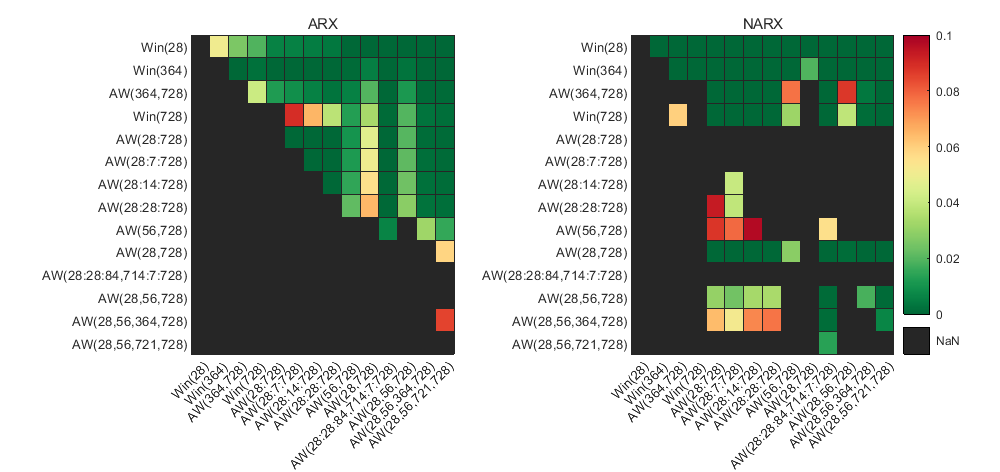

%{
Results of the multivariate DM test for selected window sets and
the ARX (left) and NARX (right) models. We use a heat map to indicate
the range of the p-values – the closer they are to zero (→ dark green) the
more significant is the difference between the forecasts of a set on the X-axis
(better) and the forecasts of a set on the Y-axis (worse).
%}
abs_error_day = nan(354,14);
narx_abs_error_day = nan(354,14);
for i = 1:354
    abs_error_day(i,:) =  sum(abs_err(1+(i-1)*24:24*i,:));
    narx_abs_error_day(i,:) =  sum(narx_abs_err(1+(i-1)*24:24*i,:));
end
DM_result_arx = nan(14,14);
DM_result_narx = nan(14,14);
for i = 1:14
    for j = 1:14
         DM_result_arx(i,j) = dmtest(abs_error_day(:,i),abs_error_day(:,j),'AE',1);
         DM_result_narx(i,j) = dmtest(narx_abs_error_day(:,i),narx_abs_error_day(:,j),'AE',1);
         if DM_result_arx(i,j) >= 0.1
             DM_result_arx(i,j) = nan(1,1);
         end
         if DM_result_narx(i,j) >= 0.1
             DM_result_narx(i,j) = nan(1,1);
         end
    end
end

figure('units','normalized','position',[0.1,0.1,1.6,1.2])
subplot(1,2,1)
xvalues = {'Win(28)','Win(364)','AW(364,728)','Win(728)','AW(28:728)','AW(28:7:728)',...
    'AW(28:14:728)','AW(28:28:728)','AW(56,728)','AW(28,728)','AW(28:28:84,714:7:728)',...
    'AW(28,56,728)','AW(28,56,364,728)','AW(28,56,721,728)'};

yvalues = {'Win(28)','Win(364)','AW(364,728)','Win(728)','AW(28:728)','AW(28:7:728)',...
    'AW(28:14:728)','AW(28:28:728)','AW(56,728)','AW(28,728)','AW(28:28:84,714:7:728)',...
    'AW(28,56,728)','AW(28,56,364,728)','AW(28,56,721,728)'};
h = heatmap(xvalues,yvalues,DM_result_arx,'FontSize',8);
h.Title = 'ARX';
h.CellLabelColor = 'none';
color = load("color.csv");
new_color = nan(size(color));
colormap(new_color)
for i = 1:size(color,1)
    new_color(i,:) = color(256-(i-1),:);
end
h.ColorLimits = [0 0.1];
h.ColorbarVisible = 'off';
subplot(1,2,2)
xvalues = {'Win(28)','Win(364)','AW(364,728)','Win(728)','AW(28:728)','AW(28:7:728)',...
    'AW(28:14:728)','AW(28:28:728)','AW(56,728)','AW(28,728)','AW(28:28:84,714:7:728)',...
    'AW(28,56,728)','AW(28,56,364,728)','AW(28,56,721,728)'};
yvalues = {'Win(28)','Win(364)','AW(364,728)','Win(728)','AW(28:728)','AW(28:7:728)',...
    'AW(28:14:728)','AW(28:28:728)','AW(56,728)','AW(28,728)','AW(28:28:84,714:7:728)',...
    'AW(28,56,728)','AW(28,56,364,728)','AW(28,56,721,728)'};
h = heatmap(xvalues,yvalues,DM_result_narx,'FontSize',8);
h.Title = 'NARX';
h.CellLabelColor = 'none';
colormap(new_color)
h.ColorLimits = [0 0.1];

function [arx_result] = epf_arx(data,ndays,startd,endd)
% input: YYYYMMDD,HH,Zonal price,System load,Zonal load, day of the week
% output：forecasted electricity price 
i=data(1,6);% weekday of starting day
N = size(data,1);
data = [data zeros(N,4)];
% get pd,min and dummies
for j=1:24:N
    switch mod(i,7)
        case 1 
            data(j:j+23,7)=1;
        case 6 
            data(j:j+23,8)=1;  
        case 0
            data(j:j+23,9)=1;
    end
    i=i+1;
    data(j:j+23,10) = min(data(j:j+23,3));
end
% the log of price
price = log(data(:,3));
% the log of system load zt
load = log(data(:,4));
% the log of min price
price_min = log(data(:,10));
arx_result = nan(ndays*24,1); % Initialize result matrix
data_arx = [price price_min load data(:,7:9)];
for j = 1:ndays
    % get every hour forecast of jth day
    for h = 1:24
        data_h = data_arx(h:24:end,:);
        data_roll = data_h(startd+(j-1):endd+j,:);
        arx_price = data_roll(1:end-1,1);
        arx_price_min = data_roll(1:end-1,2);
        arx_load = data_roll(2:end,3);
        arx_dummies = data_roll(2:end,4:6);
        y = arx_price(8:end);
        % define explanatory variables for calibration
        x = [ones(size(y)) arx_price(7:end-1) arx_price(6:end-2)...
            arx_price(1:end-7) arx_price_min(7:end-1) arx_load(7:end-1)...
            arx_dummies(7:end-1,1:3)]; 
        % define explanatory variables for day d+1
        x_fut = [1 arx_price(end) arx_price(end-1) arx_price(end-6)...
                 arx_price_min(end) arx_load(end) arx_dummies(end,1:3)];
        beta = regress(y,x);
        prog = x_fut * beta;
        % forecast price for every h hour in different days
        arx_result((j-1)*24+h,1) = exp(prog);
    end
end
end

%% DM test
function DM_pval = dmtest(e1,e2,option,h)
% Initialization
T = size(e1,1);
% Define the loss differential
if option == "AE"
    d = e1 - e2;
elseif option == "SE"
    d = e1.^2 - e2.^2;
else
    disp('incorrect option')
end
dMean = mean(d);
gamma0 = var(d);
if h > 1
    gamma = zeros(h-1,1);
    for i = 1:h-1
        sampleCov = cov(d(1+i:T),d(1:T-i));
        gamma(i) = sampleCov(2);
    end
    varD = gamma0 + 2*sum(gamma);
else
    varD = gamma0;
end
DM = dMean / sqrt((1/T)*varD);
DM_pval = 1- normcdf(DM);
end